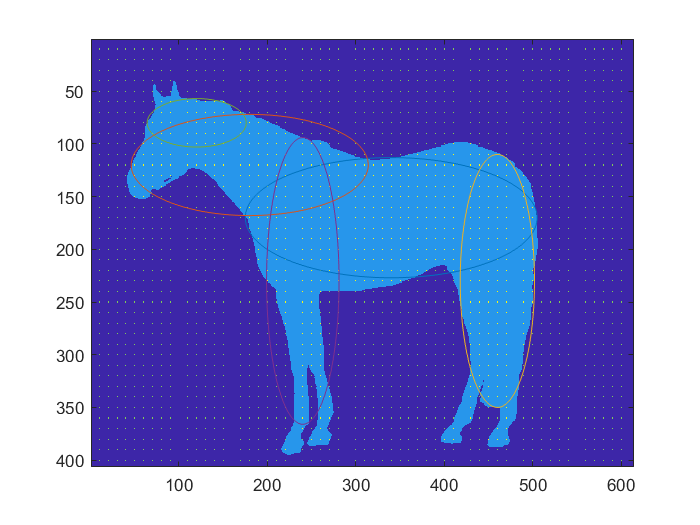

COI2 = COI;
insiders = length(all_dim);

imagesc(POI)
hold on

for j = 1:5
    
    sums = zeros([length(all_dim) 1]);
    v1s = zeros([length(all_dim) 301]);
    v2s = zeros([length(all_dim) 301]);
    ins = zeros([length(all_dim) insiders]);
   
    
    for i = 1:length(all_dim)
        %imagesc(POI);
        %hold on;
        
        [v1,v2] = ellipse2(all_dim(i,1),all_dim(i,2),0,points(i,1),points(i,2));
        v1s(i,:) = v1;
        v2s(i,:) = v2;
        
        %plot(v1,v2)
        
        in = inpolygon(COI2(:,2),COI2(:,1),v1,v2);
        ins(i,:) = in;
        
        sums(i) = sum(in);
    end
    
    m = find(sums == max(sums));
    COI2(ins(m,:) == 1,:) = [];
    insiders = insiders - max(sums);
    
    
    plot(v1s(m,:),v2s(m,:));
    
end